# **Properties of the Hodgkin-Huxley equations**

## Bandara D.M.D.V.

hhconst;

## Threshold

** Question 1**

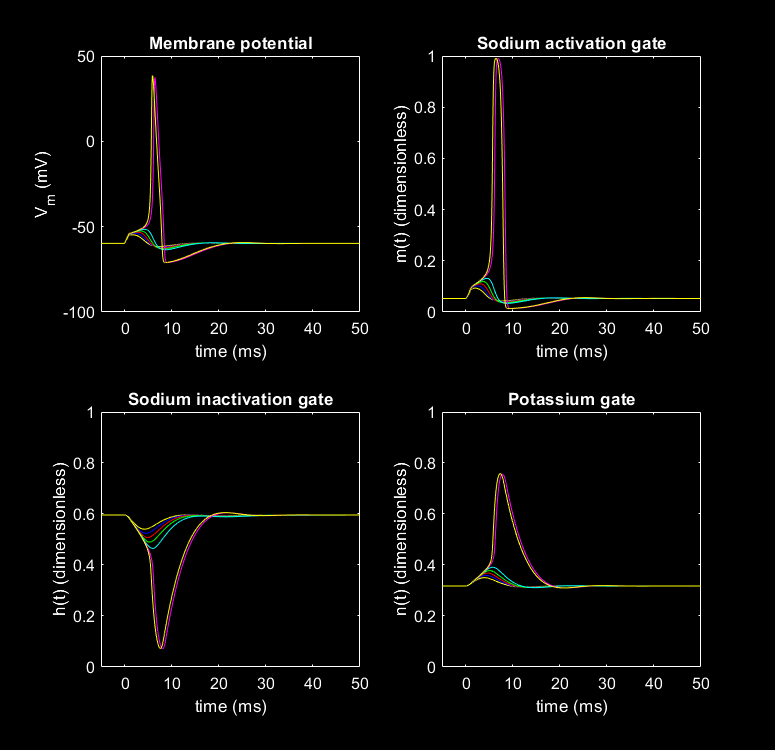

    6.5000

    6.7500

    6.8750

    6.9375

    6.9688

    6.9844



amp1=6;
width1=1;
hhmplot(0,50,0);
%amp1=7;
%hhmplot(0,50,1);
n=1;
while true
    amp1=(amp1+7)/2;
    disp(amp1);
    hhmplot(0,50,1);
    if n>5
        break
    end
    n=n+1;
end

`From the graphs we can say that the threhold lie above 0.9375 and below 6.9688 To find the closest threshold value to second decimal place following samples are used.`

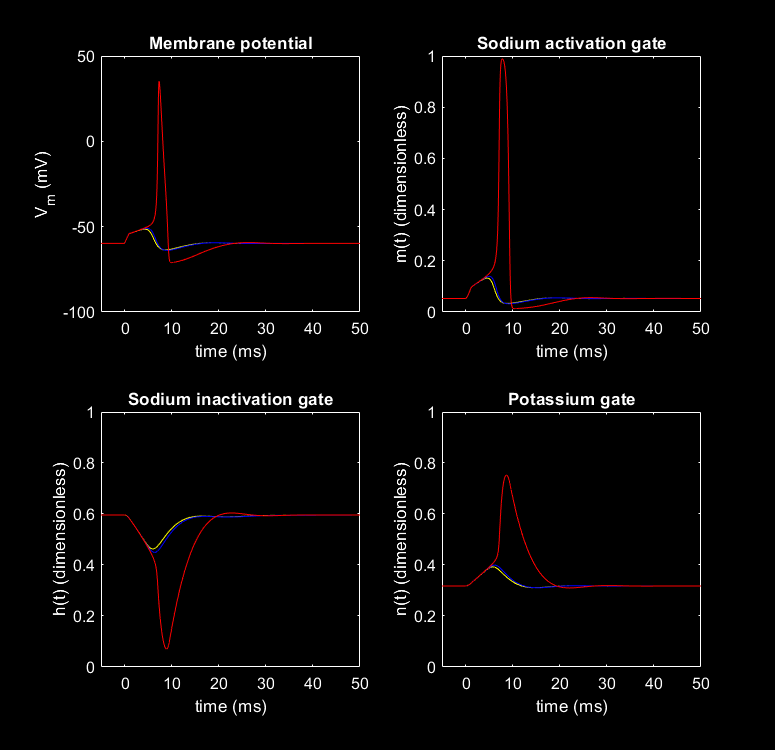

amp1=6.94;
hhmplot(0,50,0);
amp1=6.95;
hhmplot(0,50,1);
amp1=6.96;
hhmplot(0,50,1);

From the graphs we can estimate that the threshold is at 6.96$\mu A{\textrm{cm}}^{-2}$.

(Different approach is described in the explanations.)

Question 2

total_Current_densities = 3.9999

Sum_Jei = 4

total_Current_densities = 4.9998

Sum_Jei = 5

total_Current_densities = 6.9620

Sum_Jei = 6.9600

total_Current_densities = 8.9984

Sum_Jei = 9

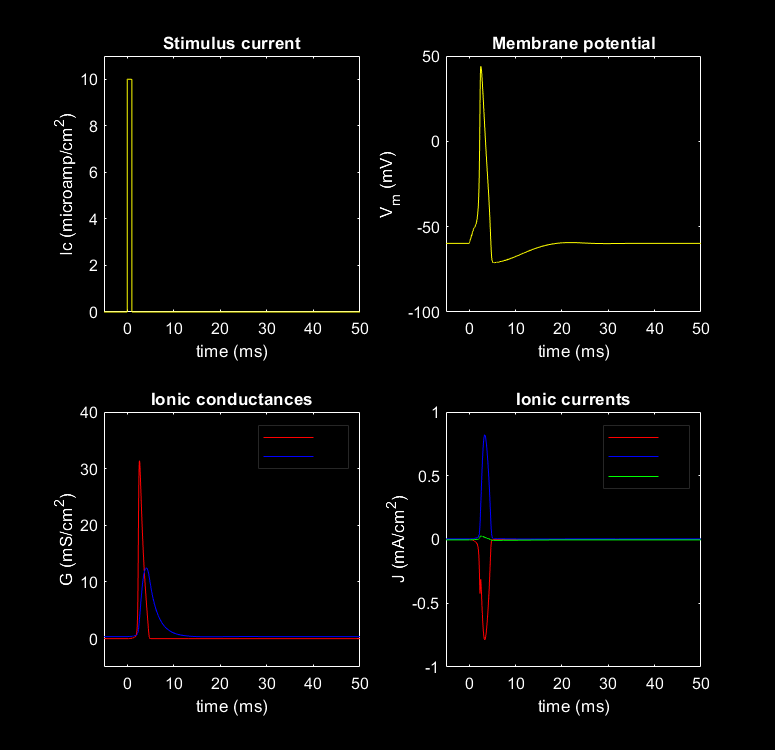

total_Current_densities = 9.9984

Sum_Jei = 10

for amp1 = [4 5 6.96 9 10]
    [qna,qk,ql]=hhsplot(0,50);
    total_Current_densities=qna+qk+ql
    Sum_Jei=width1*amp1
end

Therefore $\[ \int_{t_0}^{t_f} \sum_{k}J_k \,dt \approx \int_{t_0}^{t_f} J_{ei} \,dt \]$

## Refractoriness

**Question 3**

**Delay 2=25    /    amp2=13.7**

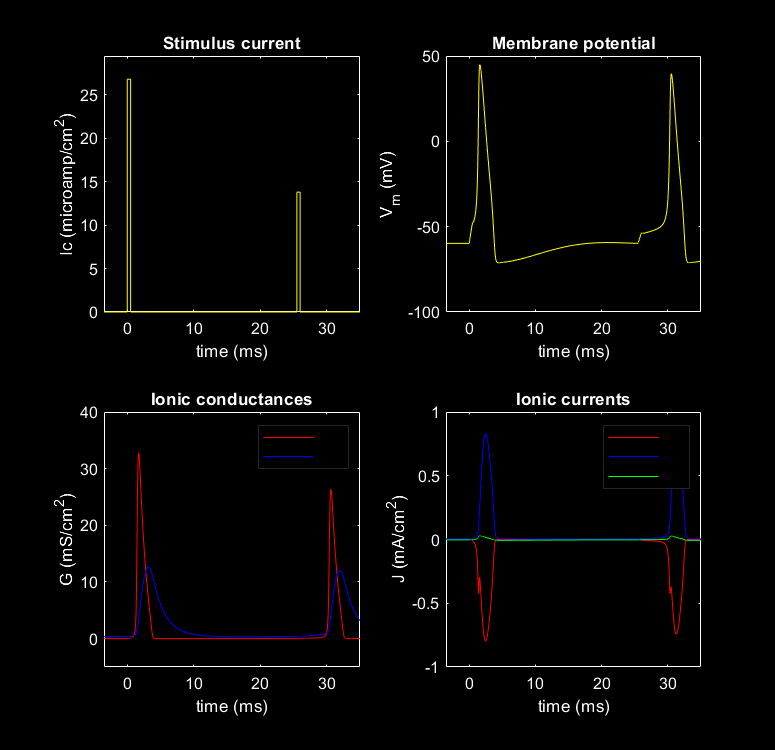

amp1 = 26.8;
width1 = 0.5;
delay2 = 25;
amp2 = 13.8;
width2 = 0.5;
hhsplot(0,35);

**Delay 2=20    /    amp2=11.6**

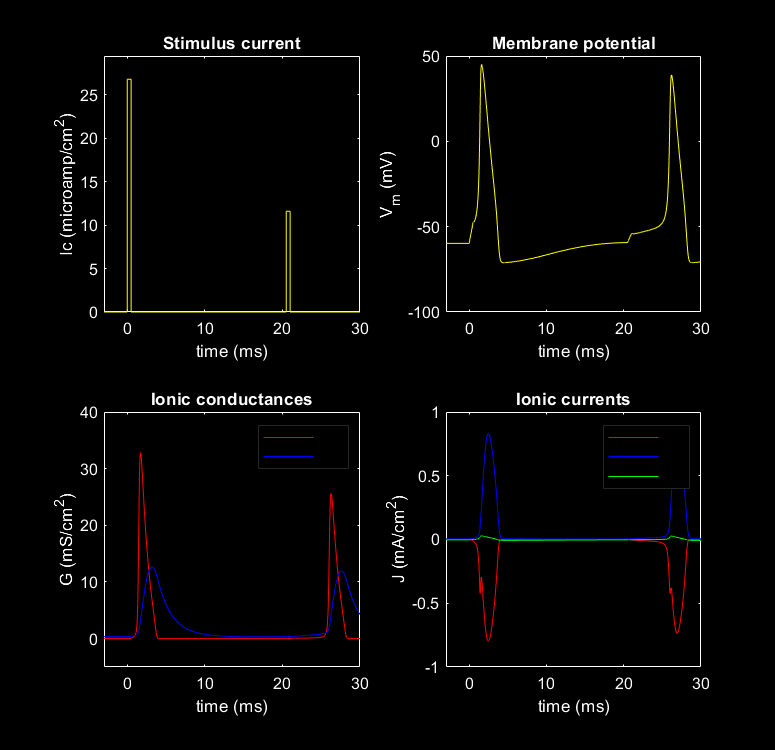

amp1 = 26.8;
width1 = 0.5;
delay2 = 20;
amp2 = 11.6;
width2 = 0.5;
hhsplot(0,30);

Delay 2=18    /    amp2=11.3

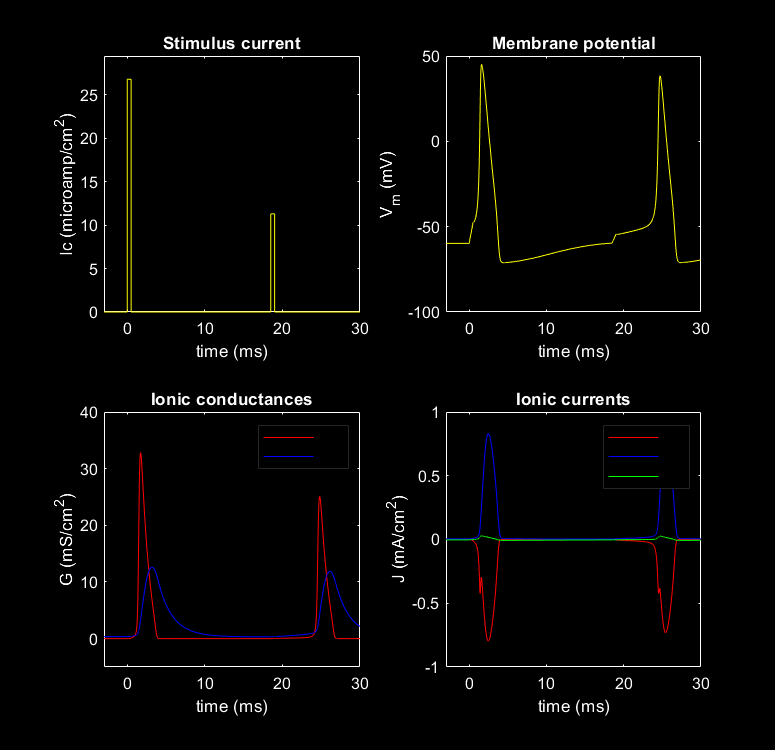

amp1 = 26.8;
width1 = 0.5;
delay2 = 18;
amp2 = 11.3;
width2 = 0.5;
hhsplot(0,30);

Delay 2=16    /    amp2=12.7

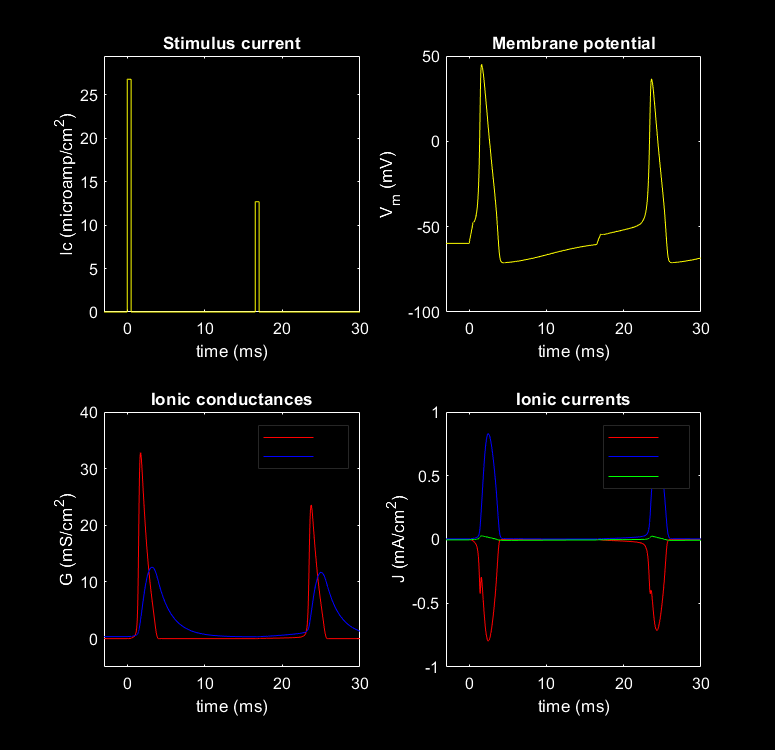

amp1 = 26.8;
width1 = 0.5;
delay2 = 16;
amp2 = 12.7;
width2 = 0.5;
hhsplot(0,30);

Delay 2=14    /    amp2=17

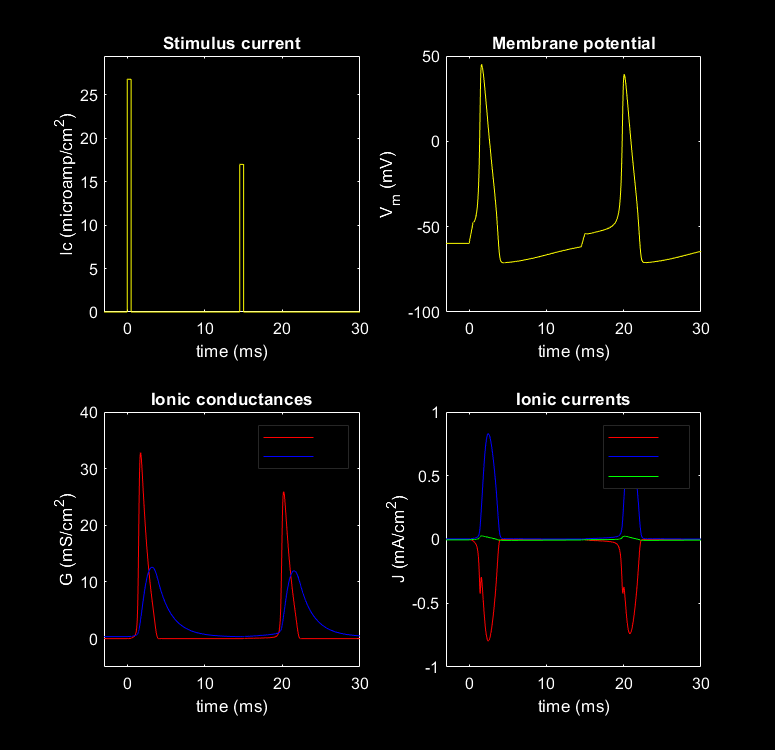

amp1 = 26.8;
width1 = 0.5;
delay2 = 14;
amp2 = 17;
width2 = 0.5;
hhsplot(0,30);

Delay 2=12    /    amp2=25.5

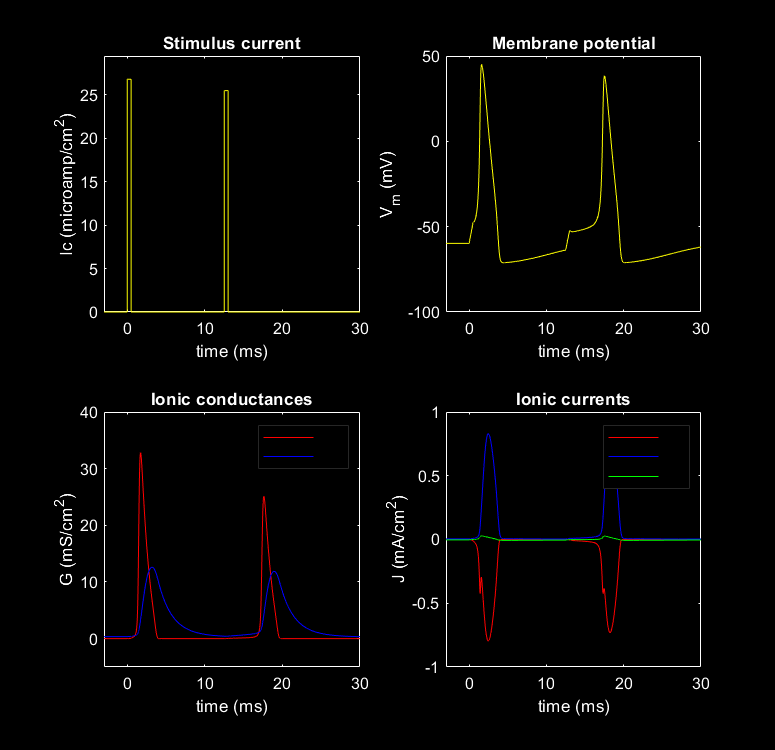

amp1 = 26.8;
width1 = 0.5;
delay2 = 12;
amp2 = 25.5;
width2 = 0.5;
hhsplot(0,30);

Delay 2=10    /    amp2=40.8

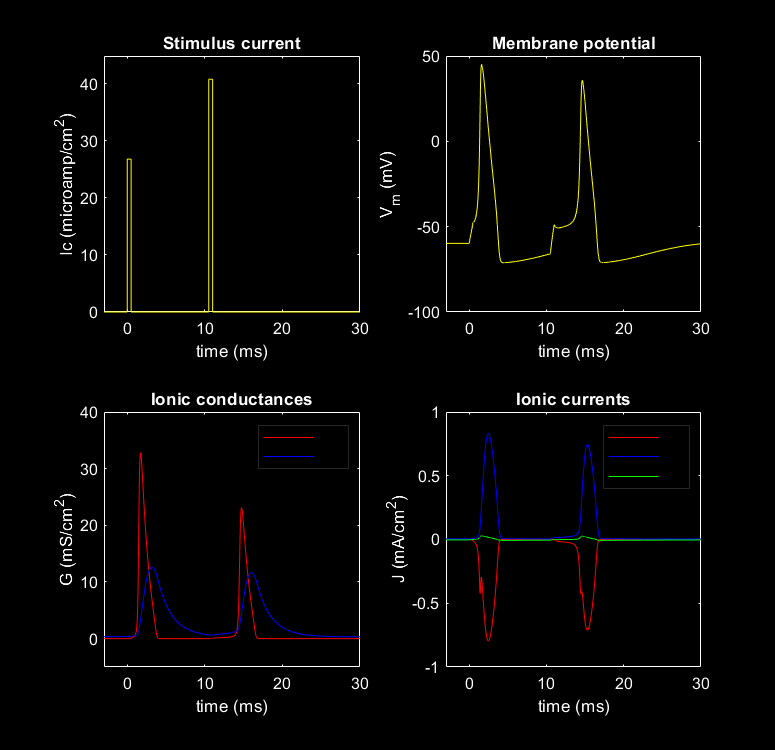

amp1 = 26.8;
width1 = 0.5;
delay2 = 10;
amp2 = 40.8;
width2 = 0.5;
hhsplot(0,30);

Delay 2=8    /    amp2=70.1

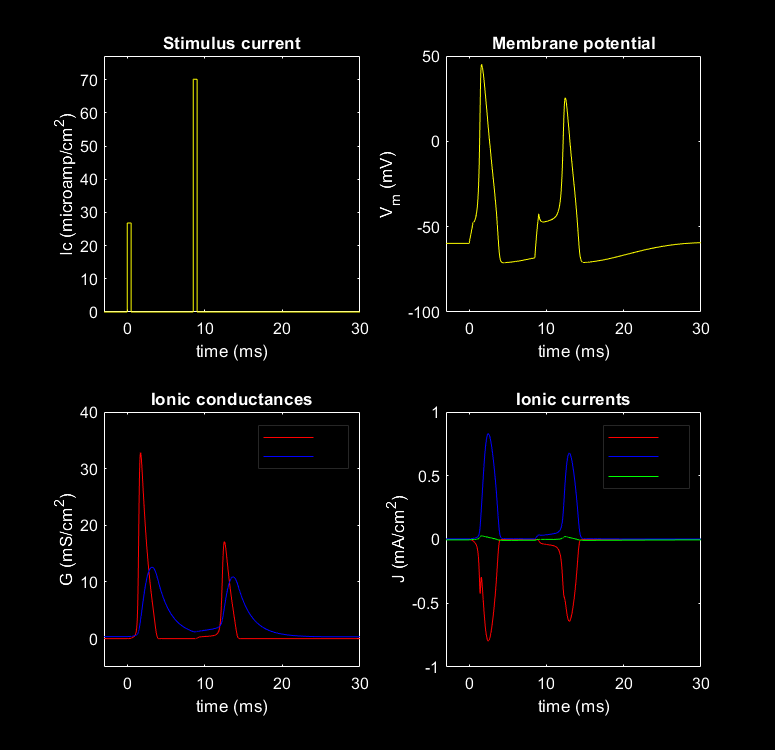

amp1 = 26.8;
width1 = 0.5;
delay2 = 8;
amp2 = 70.1;
width2 = 0.5;
hhsplot(0,30);

Delay 2=6    /    amp2=145.2

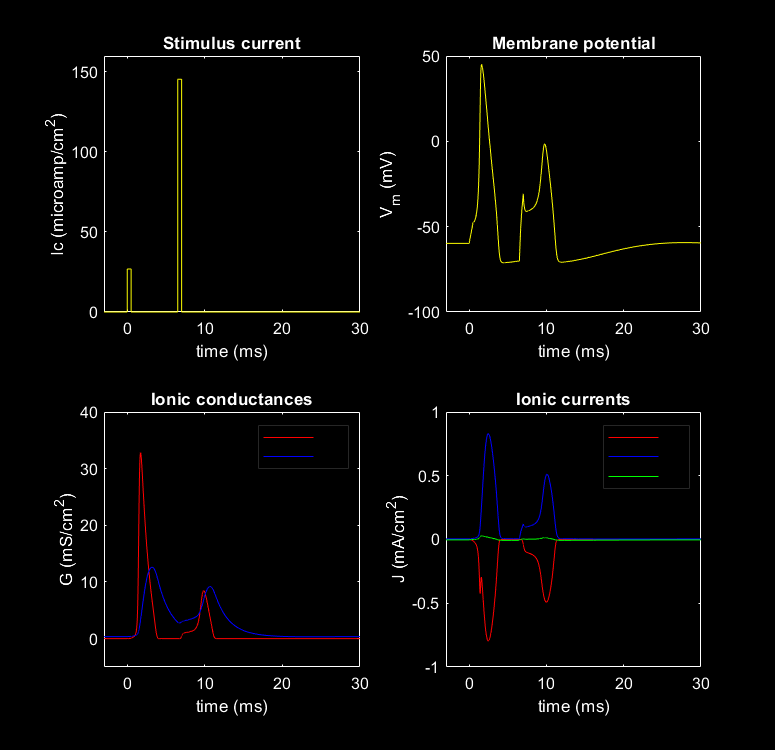

amp1 = 26.8;
width1 = 0.5;
delay2 = 6;
amp2 = 145.2;
width2 = 0.5;
hhsplot(0,30);

With the results,

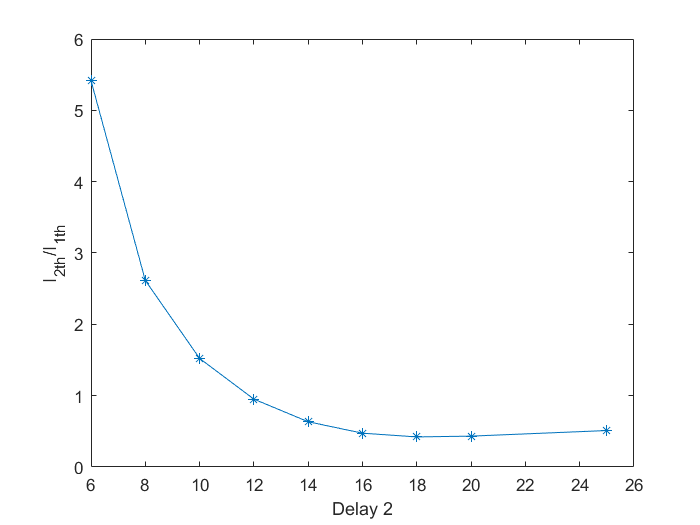

delay_2=[6 8 10 12 14 16 18 20 25];
I2th=[145.2 70.1 40.8 25.5 17 12.7 11.3 11.6 13.7]./26.8;
figure;
plot(delay_2,I2th,'*-');
xlabel("Delay 2");
ylabel('I_{2th}/I_{1th}');

$I_{2th}$ current increases exponentialy with decreasing time delay. 

At 6ms, time delay $I_{2th}$ value is more than 5 times the $I_{1th}$ current. Hence, comparatively large. So the absolute refractory period is 6ms.

Thereafter, its clear that $I_{2th}$ is grater than $I_{1th}$ current at 10ms. Therefore relative refractory period is 10ms.

## **Repetitive Activity**

**Question 5**

amp1=5  

amp1=5;
width1 = 80;
delay2 = 0;
amp2 = 0;
width2 = 0;
hhmplot(0,100,0);
%AP=1

  amp1=10 

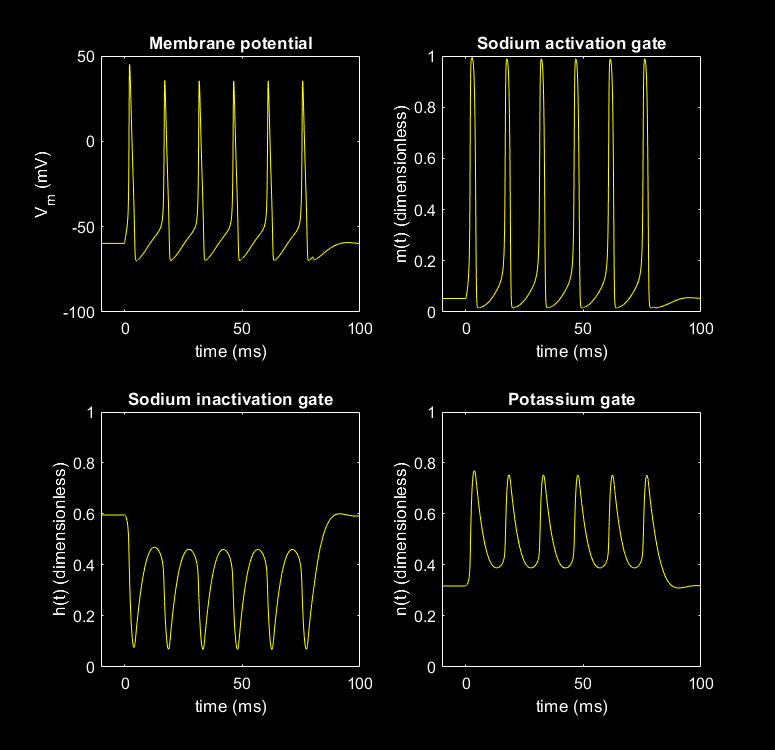

amp1=10;
width1 = 80;
delay2 = 0;
amp2 = 0;
width2 = 0;
hhmplot(0,100,0);

% AP=6

amp1=20 

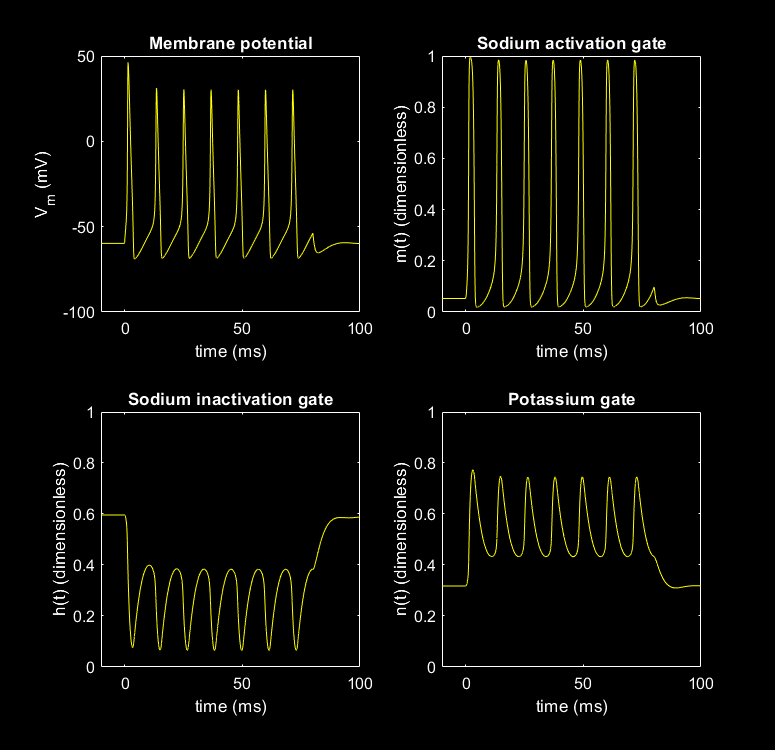

amp1=20;
width1 = 80;
delay2 = 0;
amp2 = 0;
width2 = 0;
hhmplot(0,100,0);

%AP=7

amp1=30 

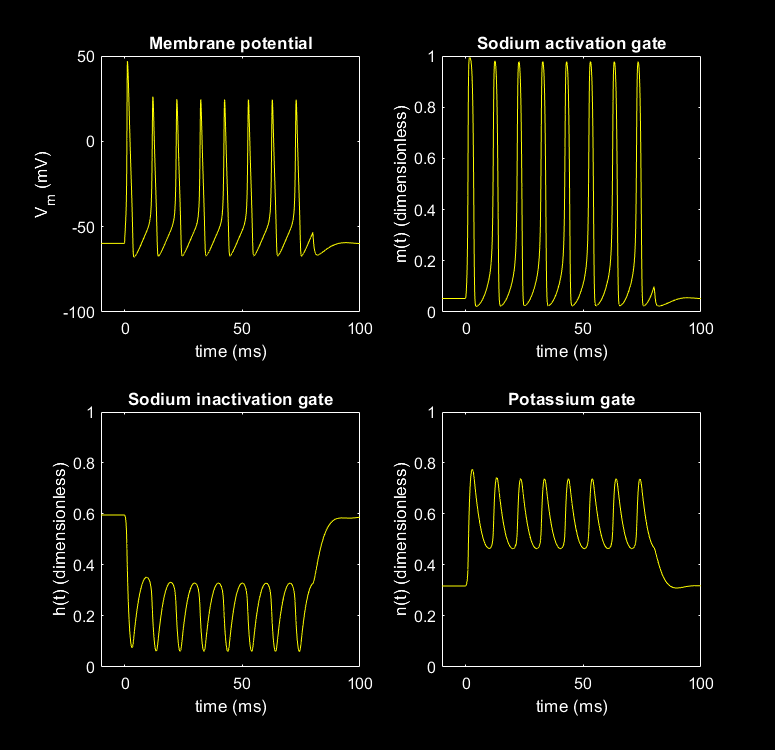

amp1=30;
width1 = 80;
delay2 = 0;
amp2 = 0;
width2 = 0;
hhmplot(0,100,0);

%AP=8

amp1=50  

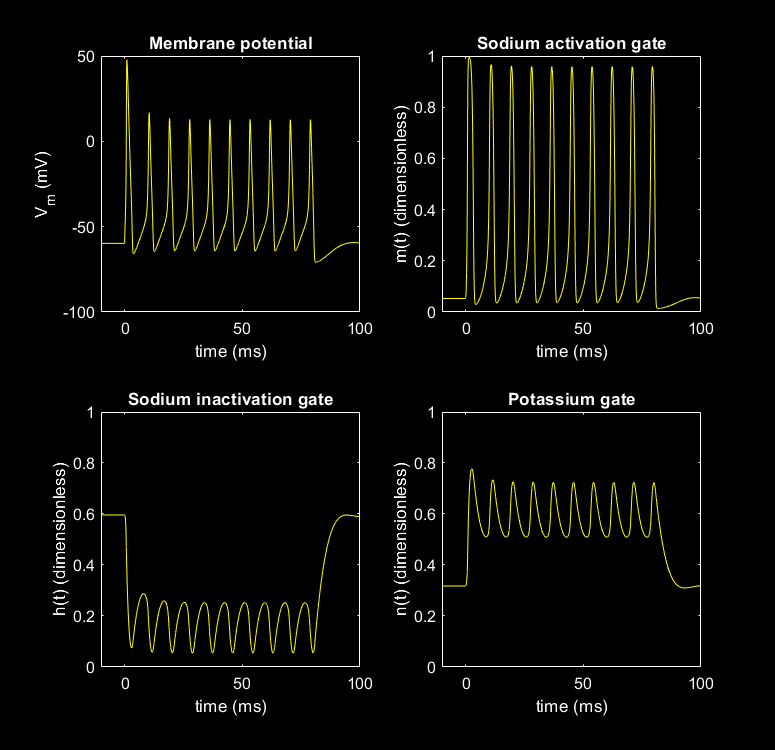

amp1=50;
width1 = 80;
delay2 = 0;
amp2 = 0;
width2 = 0;
hhmplot(0,100,0);

%AP10

amp1=70 

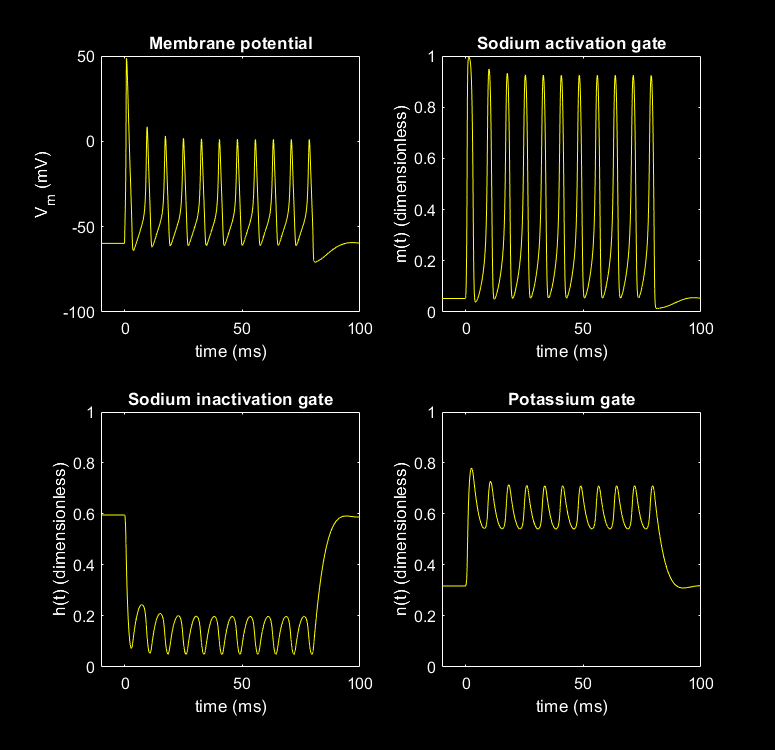

amp1=70;
width1 = 80;
delay2 = 0;
amp2 = 0;
width2 = 0;
hhmplot(0,100,0);

%AP = 11

amp1 = 100

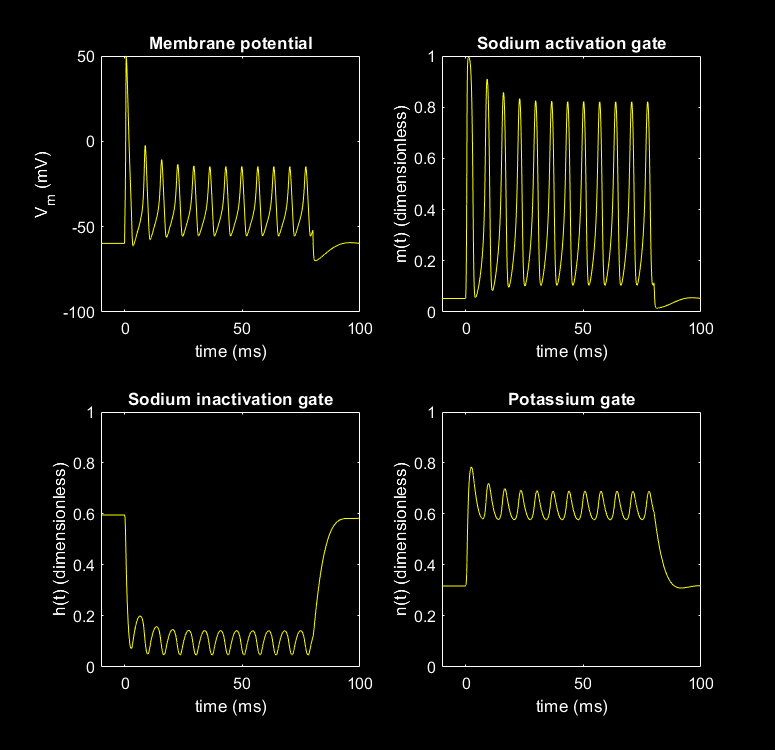

amp1=100;
width1 = 80;
delay2 = 0;
amp2 = 0;
width2 = 0;
hhmplot(0,100,0);

%AP = 12

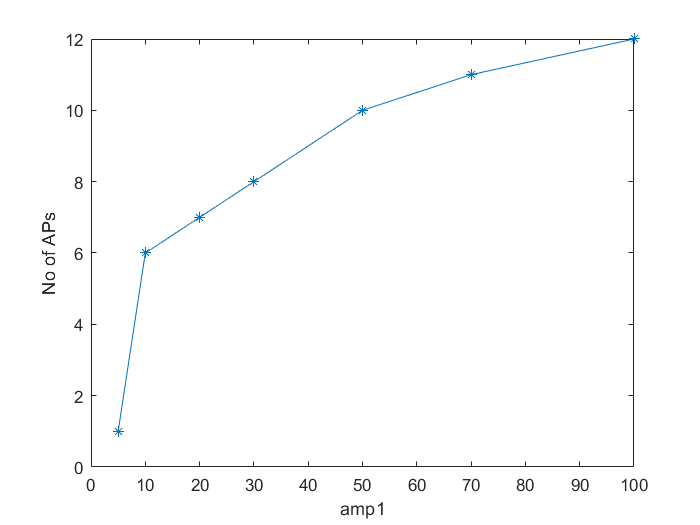


amp1=[5 10 20 30 50 70 100];
no_of_AP=[1 6 7 8 10 11 12];
figure;
plot(amp1,no_of_AP,'*-');
xlabel("amp1");
ylabel('No of APs');

Amplitude of action potential is decreasing as the AMP1 value is increasing

**Question 6**

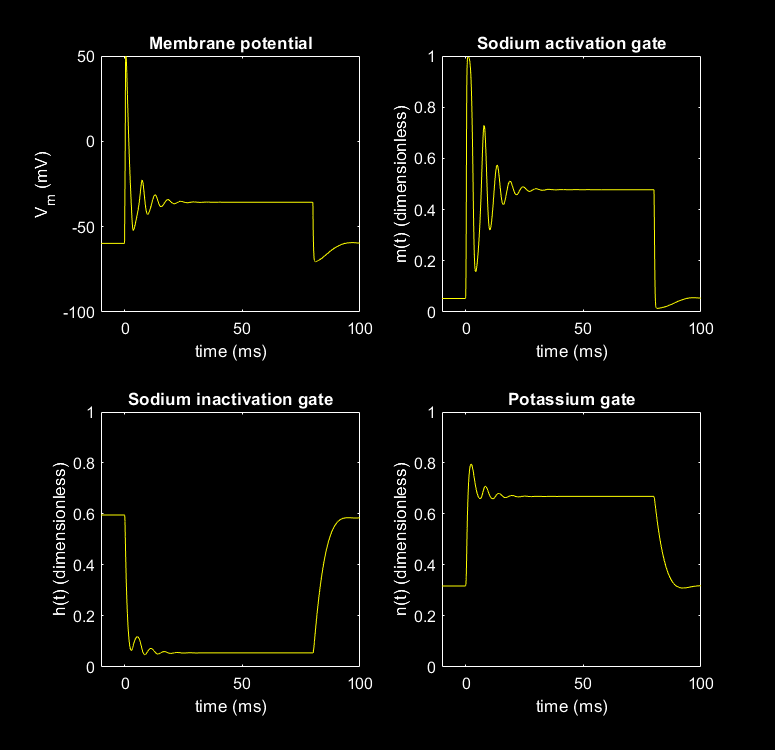

amp1=200;
width1 = 80;
delay2 = 0;
amp2 = 0;
width2 = 0;
hhmplot(0,100,0);

When the amp1 is very large instead of generating APs, it reaches a constant value\saturates.

## Temperature Dependence

**Question 7**

plotting by increasing the temperature with 5 degrees incriment to see changes

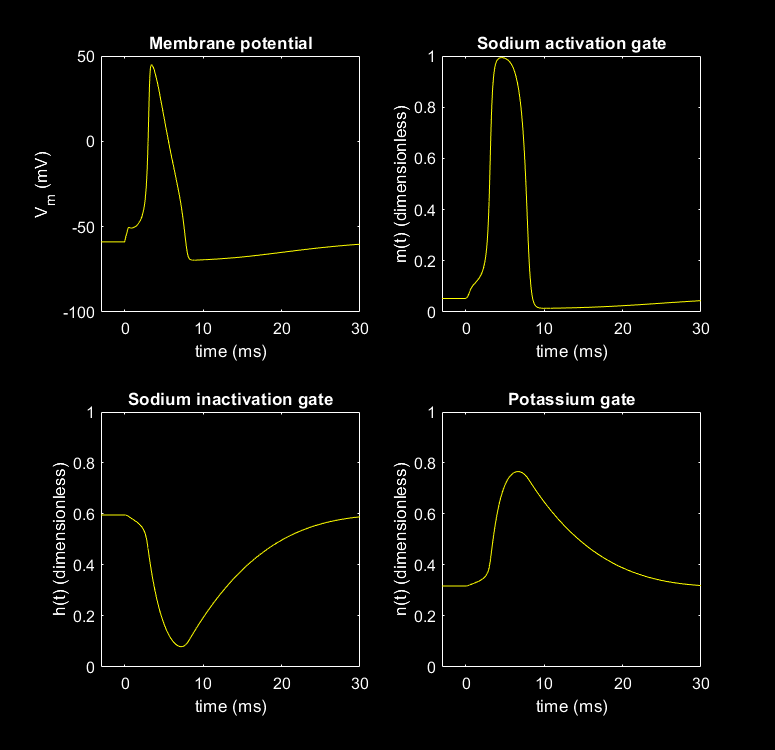

vclamp = 0;
amp1 = 20;
width1 = 0.5;
tempc = 0;
hhmplot(0,30,0);

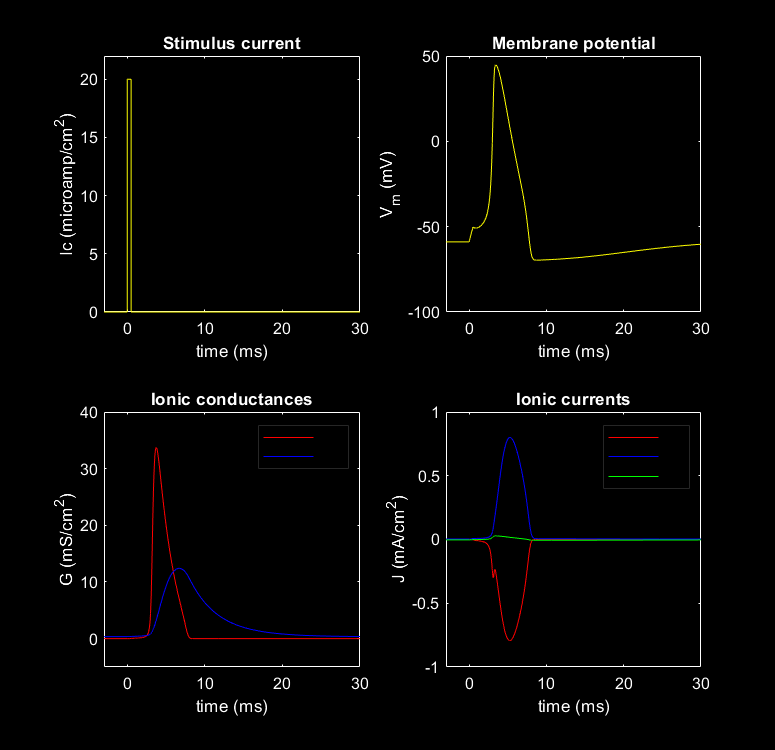

ans = -2.7016e+03

hhsplot(0,30)

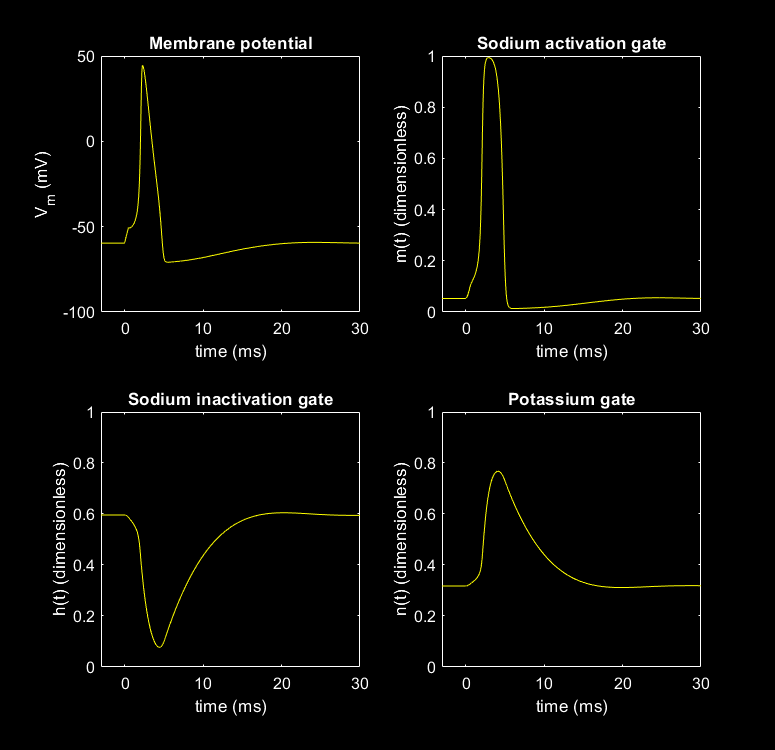

vclamp = 0;
amp1 = 20;
width1 = 0.5;
tempc = 5;
hhmplot(0,30,0);

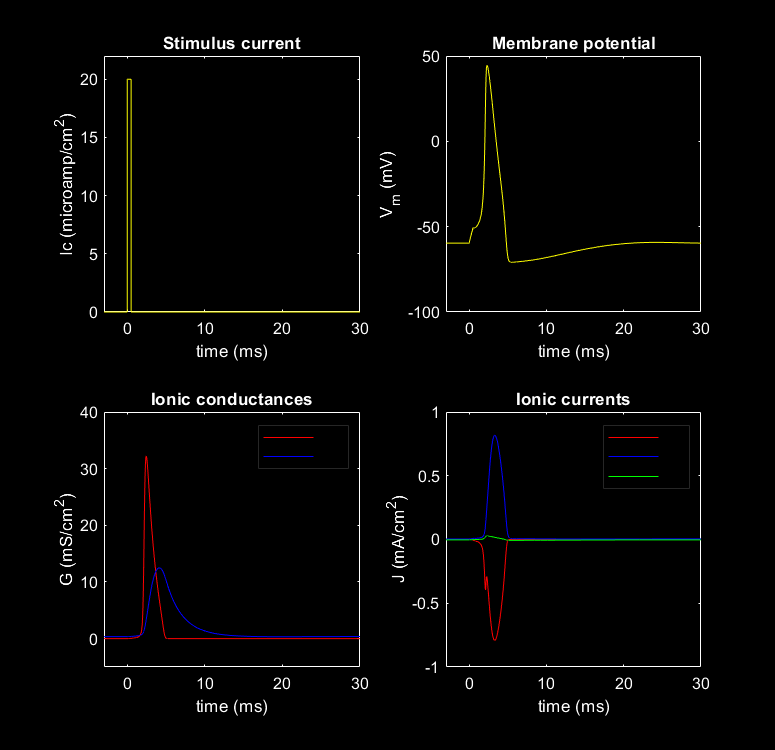

hhsplot(0,30);

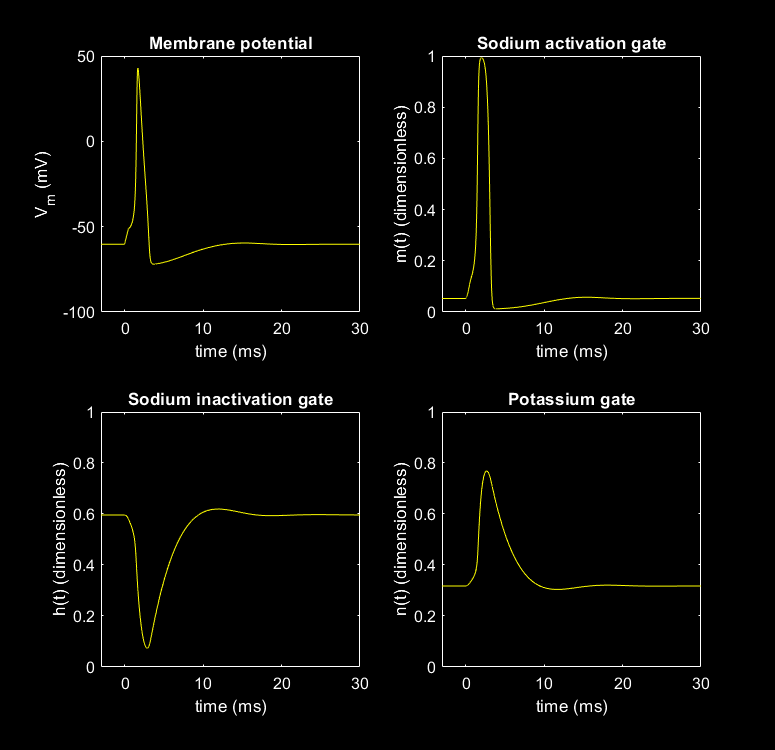

vclamp = 0;
amp1 = 20;
width1 = 0.5;
tempc = 10;
hhmplot(0,30,0);

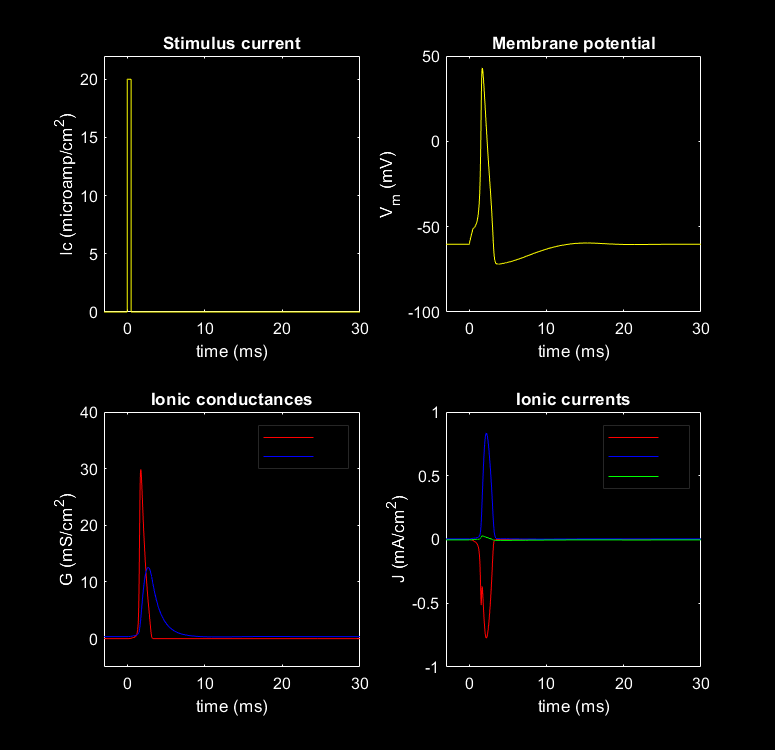

hhsplot(0,30);

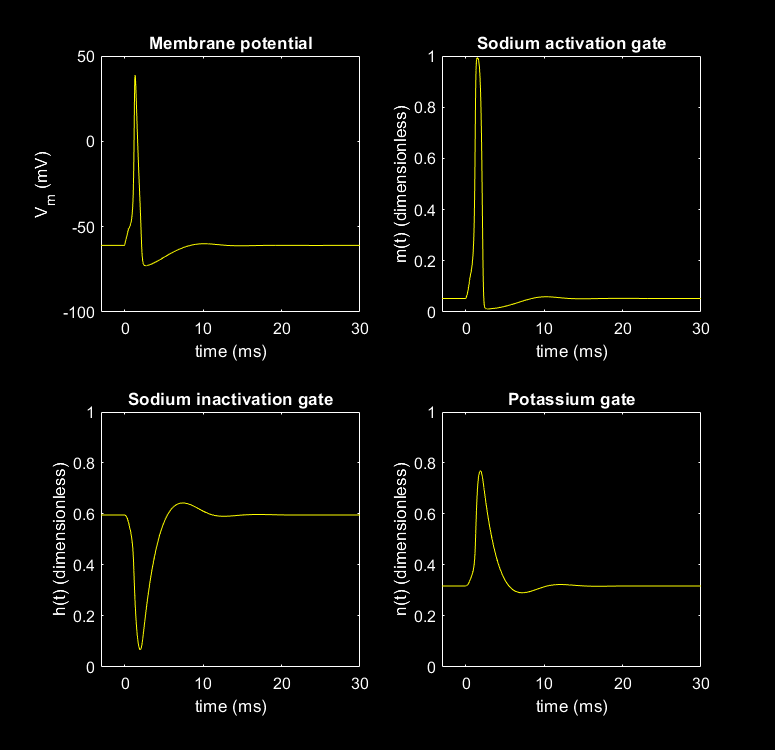

vclamp = 0;
amp1 = 20;
width1 = 0.5;
tempc = 15;
hhmplot(0,30,0);

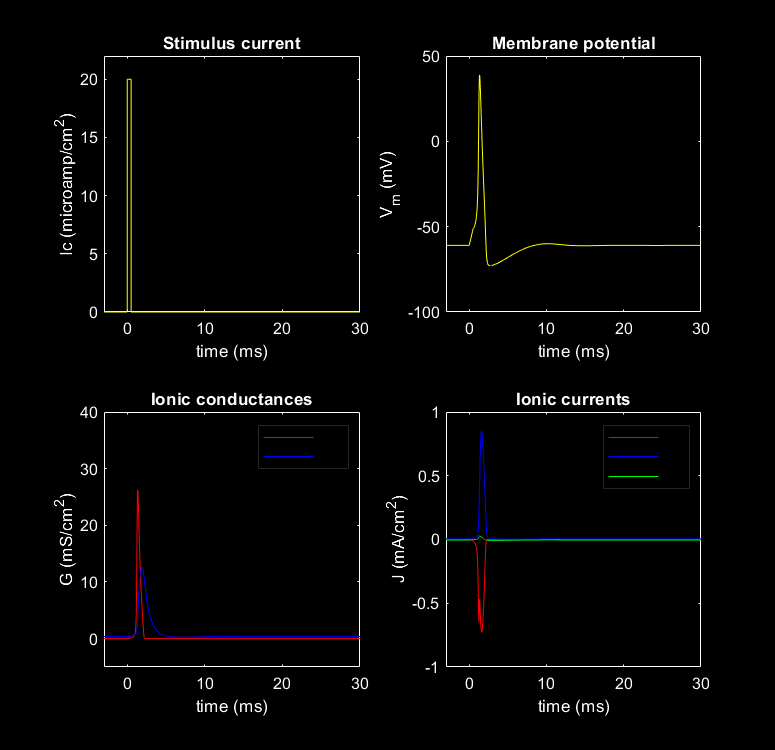

hhsplot(0,30);

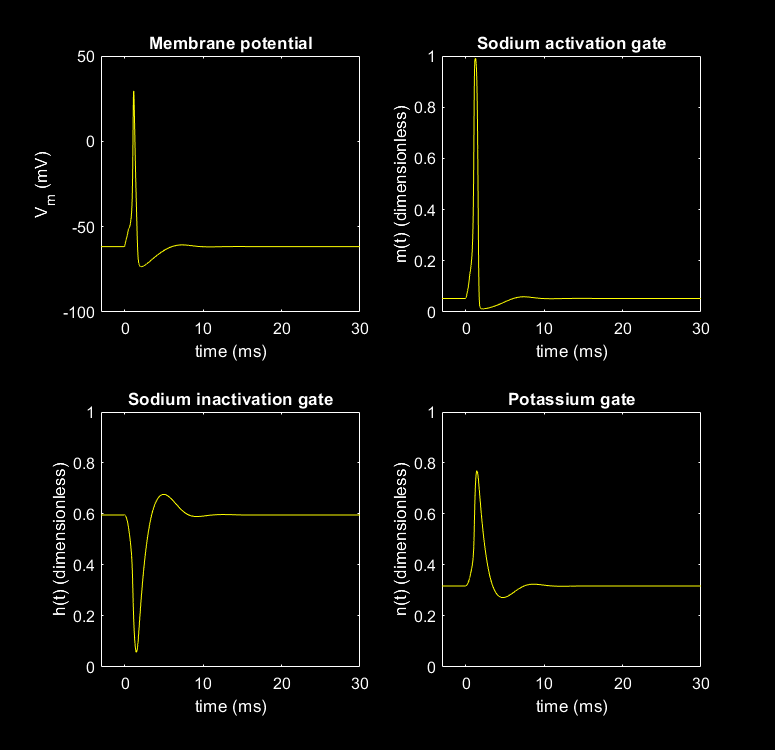

vclamp = 0;
amp1 = 20;
width1 = 0.5;
tempc = 20;
hhmplot(0,30,0);

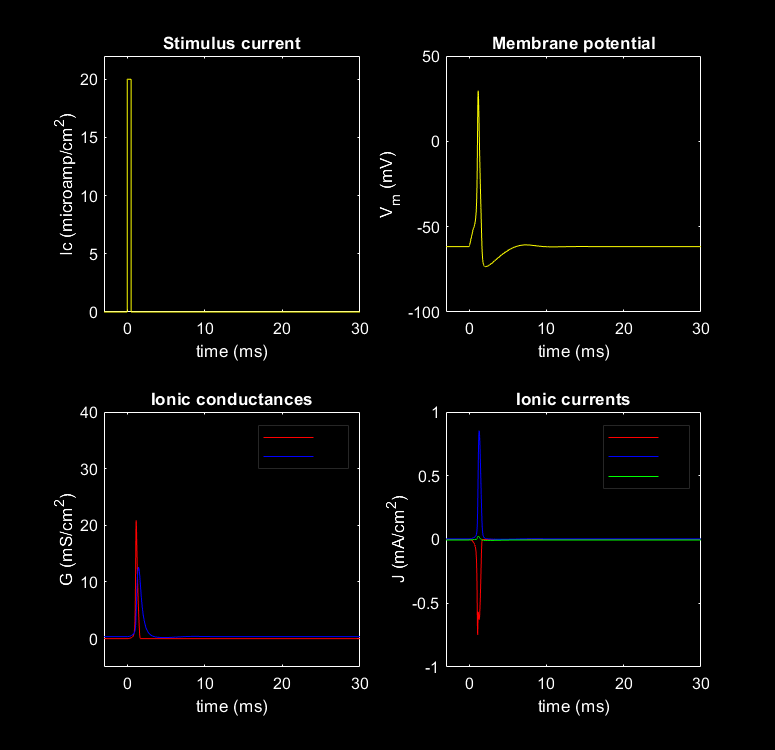

hhsplot(0,30);

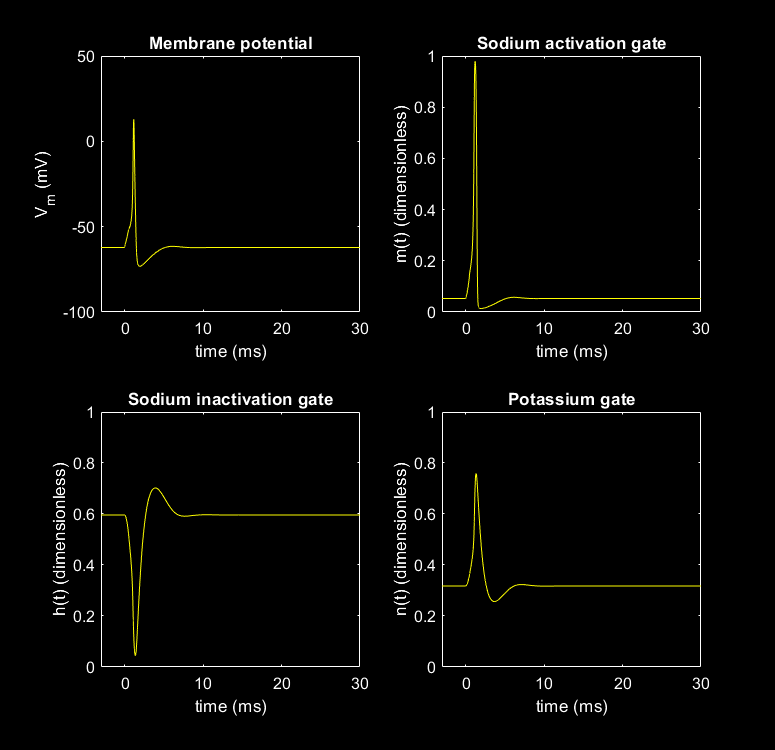

vclamp = 0;
amp1 = 20;
width1 = 0.5;
tempc = 24;
hhmplot(0,30,0);

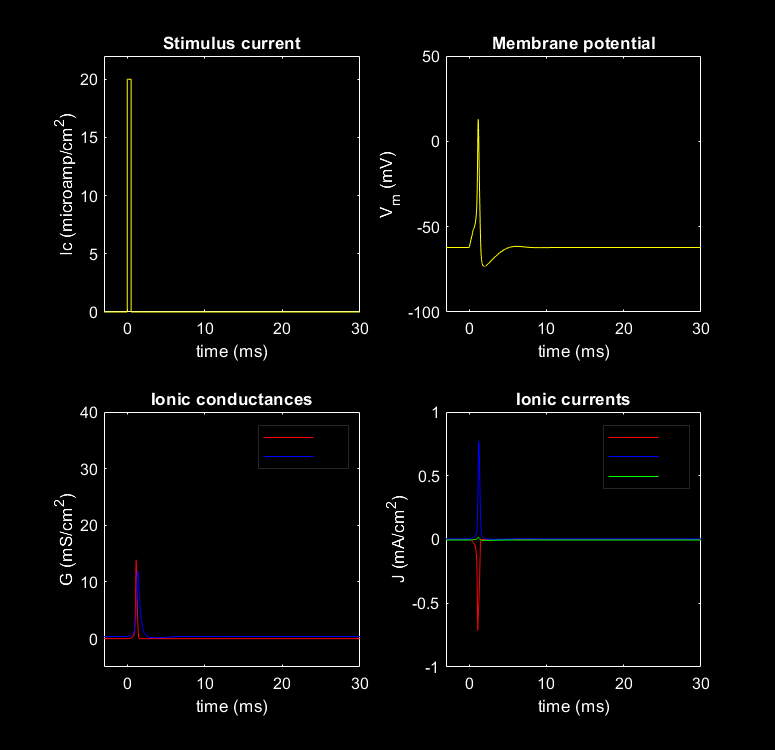

hhsplot(0,30);

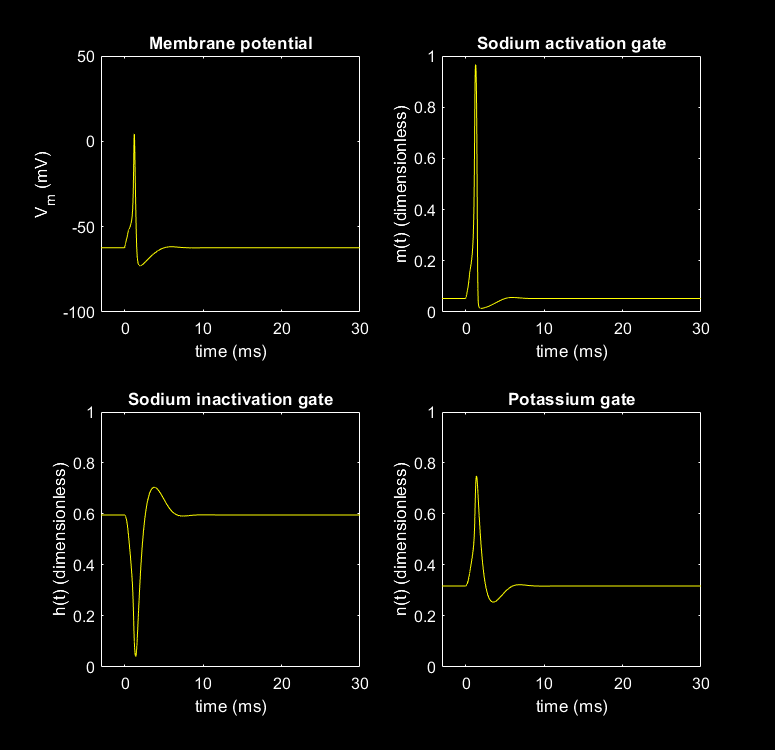

vclamp = 0;
amp1 = 20;
width1 = 0.5;
tempc = 25;
hhmplot(0,30,0);

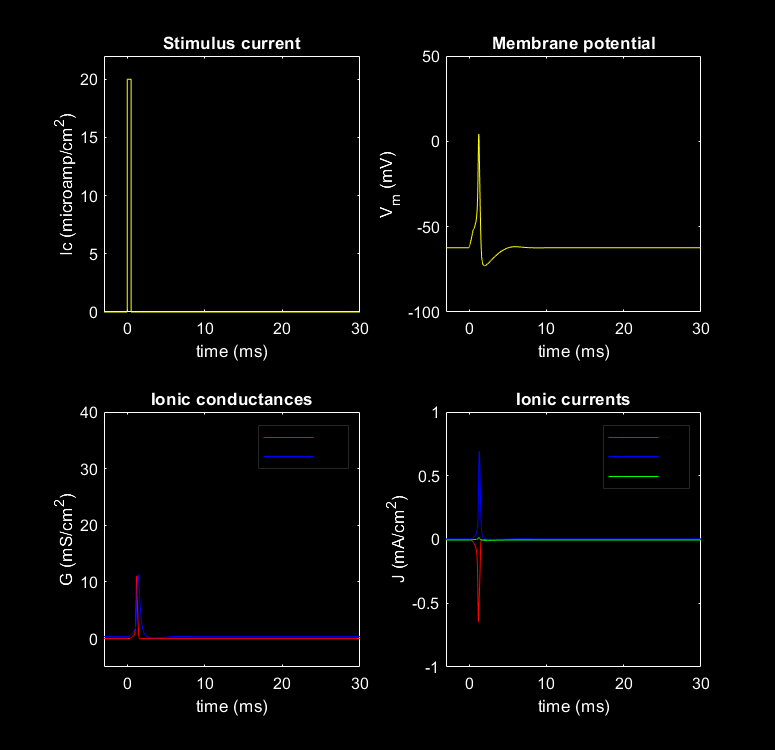

hhsplot(0,30);

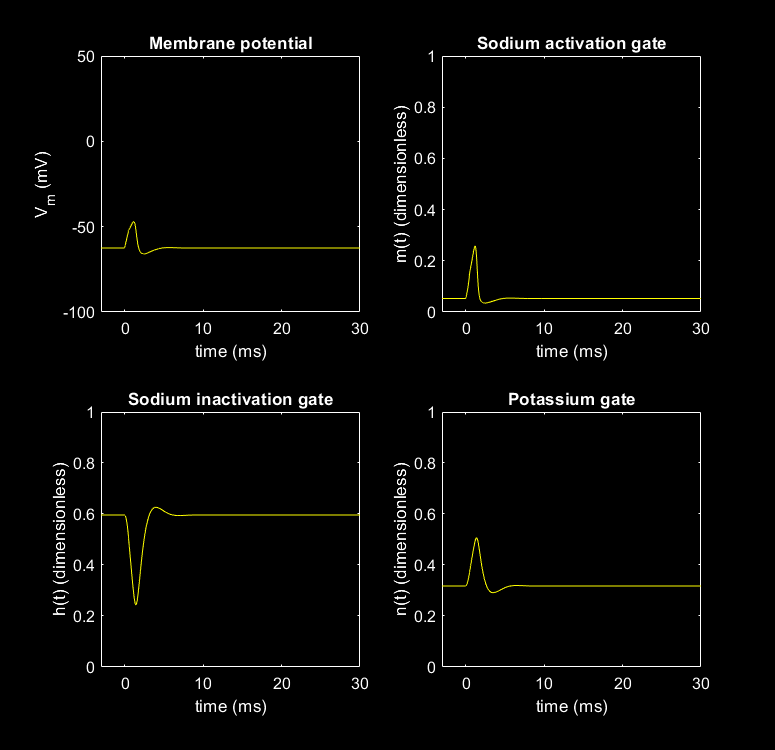

vclamp = 0;
amp1 = 20;
width1 = 0.5;
tempc = 26;
hhmplot(0,30,0);

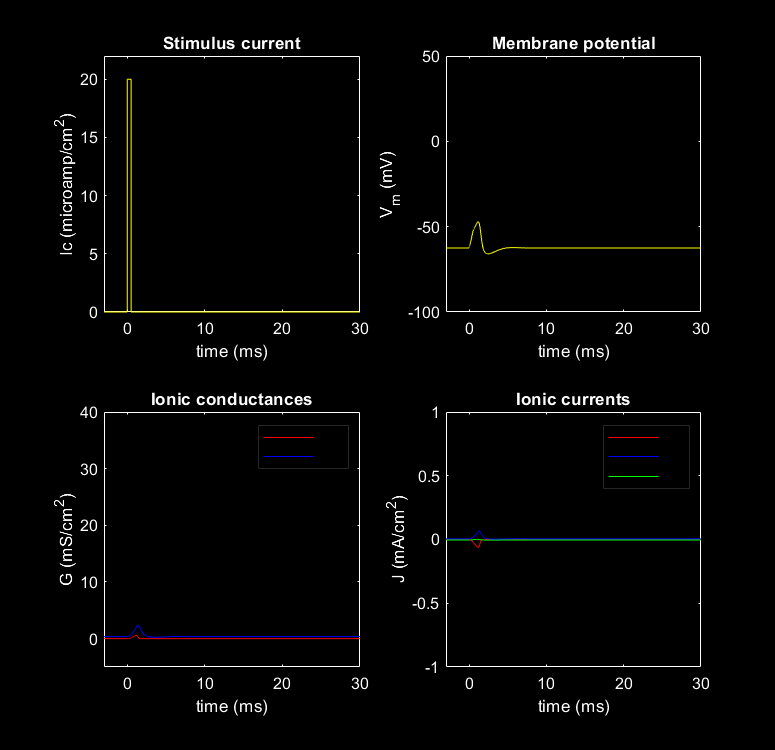

hhsplot(0,30);

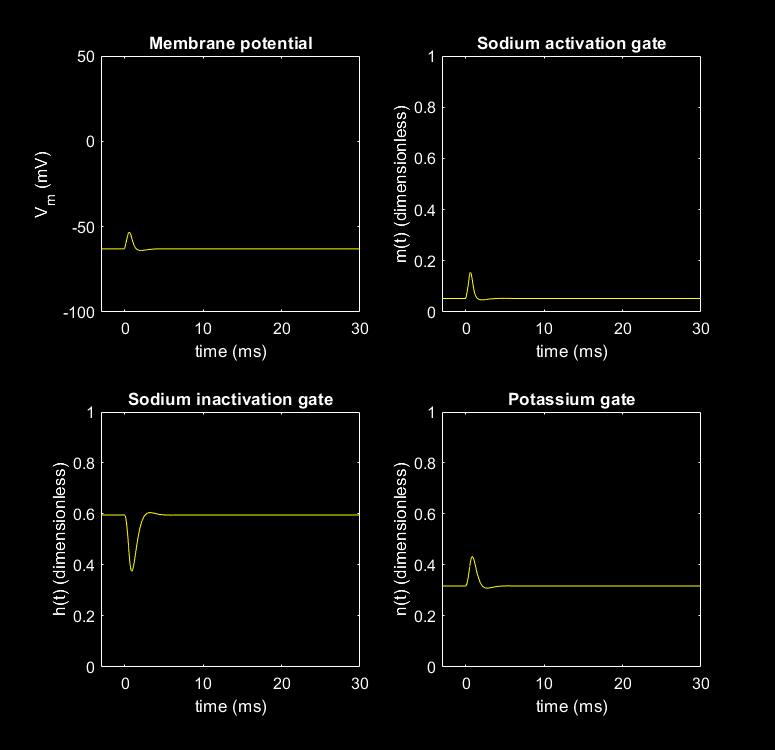

vclamp = 0;
amp1 = 20;
width1 = 0.5;
tempc = 30;
hhmplot(0,30,0);

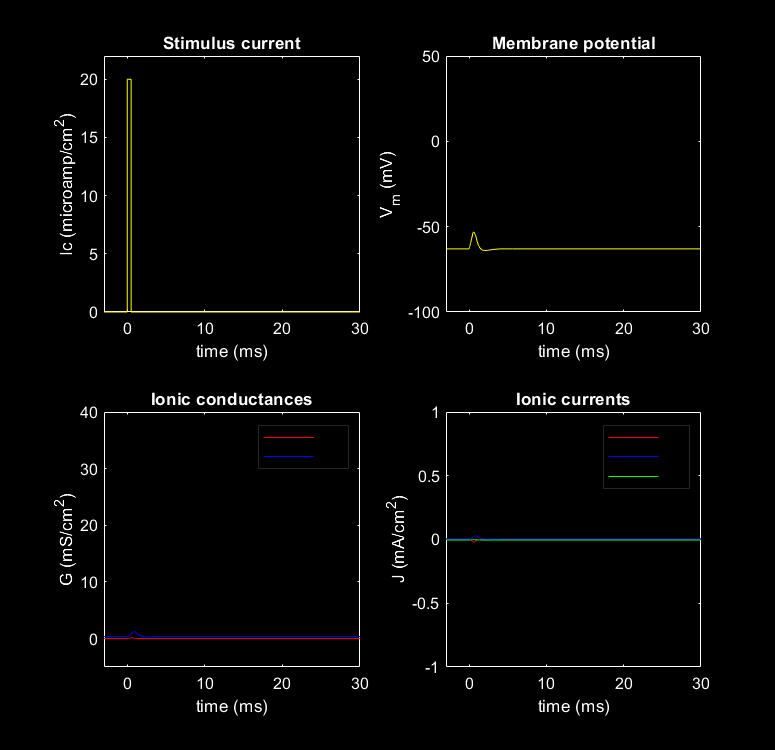

hhsplot(0,30);

Action potential amplitude as well as the threshhold is affected by the temperature.